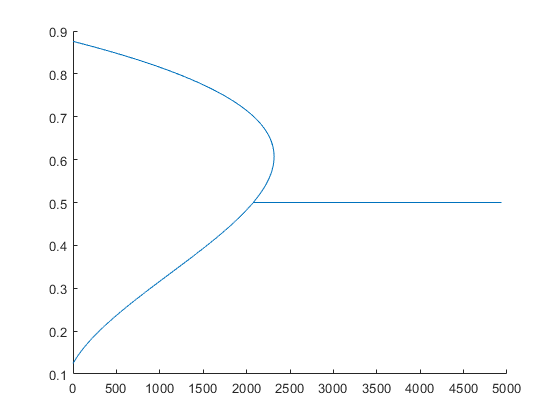

clear all
Io = 0:0.01:24.68;
ILavg = Io/2;
deltaIL = 2*ILavg + 8;

L = 6.8e-6;
fsw = 0e3;
Vin = 400;

K = deltaIL*L*fsw/Vin;
disc = 1-4*K;

root1 = real((1 + sqrt(disc))/2);
root2 = real((1 - sqrt(disc))/2);

P1 = Io.*Vin.*root1;
P2 = Io.*Vin.*root2;
P2 = flip(P2);
root2 = flip(root2);

P = [P1 P2]';
DC = [root1 root2]';
Gain = 1./DC;

figure
hold on
plot(P,DC)
hold off

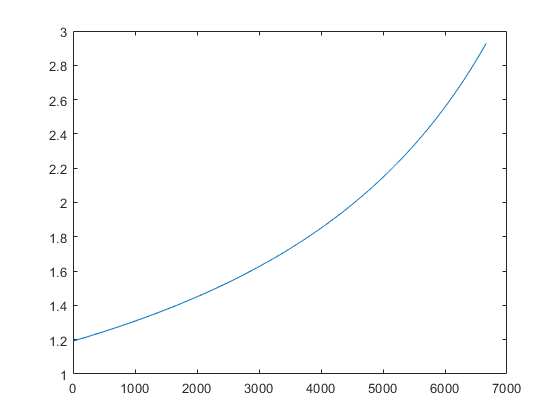

%Boost Mode
Vin = 270;
D = L*deltaIL*fsw/Vin;
Pin = Vin*Io;

Vout = Vin./(1-D);
plot(Pin,1./(1-D))